## Australia covid cases

data = readtable("Australia_covid_cases.xlsx")

data = 1322×2 table
    Date_reported    Cumulative_cases
    _____________    ________________

     03-Jan-2020            0        
     04-Jan-2020            0        
     05-Jan-2020            0        
     06-Jan-2020            0        
     07-Jan-2020            0        
     08-Jan-2020            0        
     09-Jan-2020            0        
     10-Jan-2020            0        
     11-Jan-2020            0        
     12-Jan-2020            0        
     13-Jan-2020            0        
     14-Jan-2020            0        
     15-Jan-2020            0        
     16-Jan-2020            0        
     17-Jan-2020            0        
     18-Jan-2020            0        


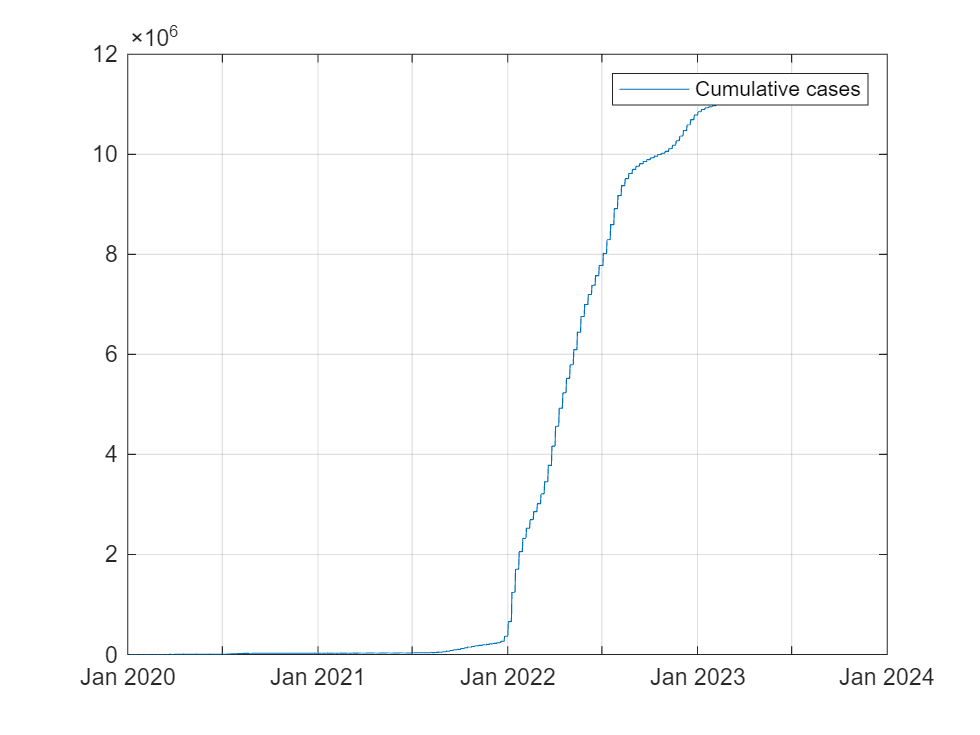


t = data.Date_reported(:);
cases = data.Cumulative_cases(:);
figure
plot(t,cases,'-','DisplayName','Cumulative cases')
legend, grid 

x = cases(1:end-10);
sys1 = ar(x,2)

sys1 =
Discrete-time AR model: A(z)y(t) = e(t)
  A(z) = 1 - z^-1 + 1.774e-05 z^-2     
                                       
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=2
   Number of free coefficients: 2
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                               
Estimated using AR ('fb/now') on time domain data "x".
Fit to estimation data: 99%                           
FPE: 2.269e+09, MSE: 2.262e+09                        
 
Model Properties


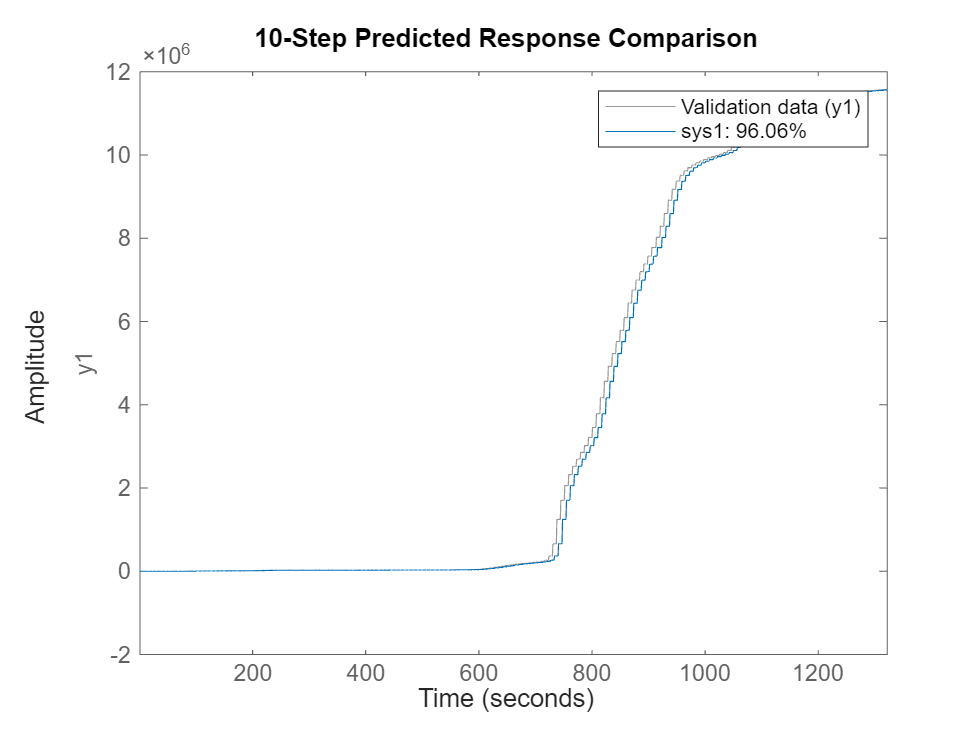

compare(cases,sys1,10)